% x=-5:10/300:5;
% y=x;
% [x,y]=meshgrid(x,y);
% z = 20 + x.^2 + y.^2- 10*(cos(2*pi*x) + cos(2*pi*y));
% surfc(x,y,z);
nvars=2;
[x,fval]=ga(@rastriginsfcn,nvars,[],[],[],[],[-5,5],[-5,5])%x:solution; fval:final value for object function
%z = 2*(1-x).^2.^exp(-(x.^2)-(y+1).^2);

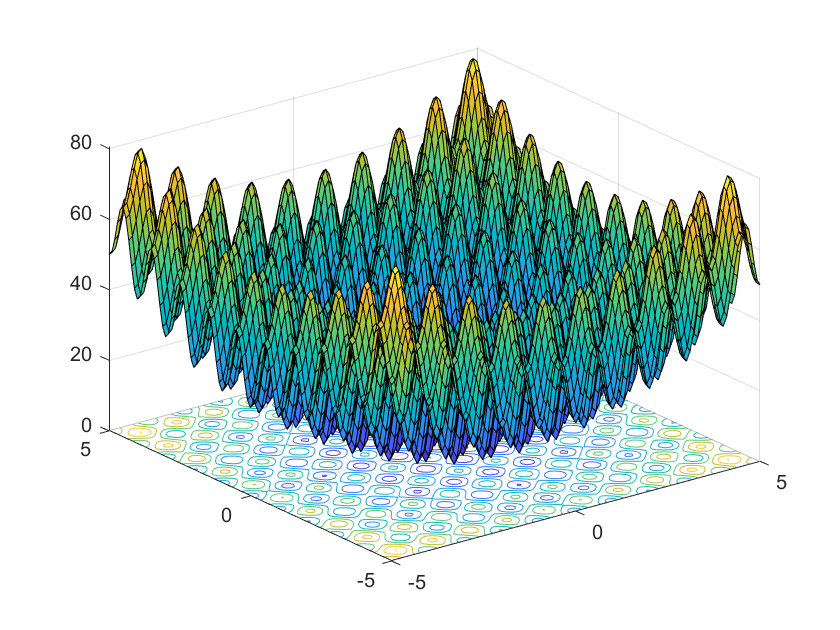

interval = 100;
x=-5:10/100:5;
y=x;
[xCor,yCor] = meshgrid(x,y);
r=zeros(interval+1);
for i=1:(interval+1)
    for j=1:(interval+1)
        r(i,j)=rastriginsfcn([xCor(i,j),yCor(i,j)]);
    end
end
surfc(xCor,yCor,r);


                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations


在当前文件夹或 MATLAB 路径中未找到 'gaintobj'，但它位于:
 C:\Users\gzliy\Documents\MATLAB\Examples\R2019b\globaloptim\CustomOutputFunctionForGeneticAlgorithmExample

更改 MATLAB 当前文件夹 或 将其文件夹添加到 MATLAB 路径。

出错 myoutputfunc (line 47)
        bestf = gaintobj(bestx);

出错 

rng default
options = optimoptions('ga','Display',"iter","OutputFcn",@myoutputfunc);
[x,fval,exitflag,output,population,scores] = ga(@rastriginsfcn,2,[],[],[],[],[],[],[],options);

x = [1:50];
plot(x,scores);
plot(x,population(:,1),x,population(:,2));
